format long

Hausarbeit 1. Prügungszeitraum - Zeitaufgelöste Photolumineszenz

Bearbeitet von:

    (A) MHD Ammar Aljouharji

    (B) Leonard Berresheim

- Einleitung

$\frac{\delta u}{\delta t}=D\frac{\delta^2 u}{\delta z^2 }-\left(k_1 +k_2 N_D \right)u-k_2 u^{2\;} +s\left(t,z\right),\;\;\;\;\;\;\;\;\;\;t\ge 0,0<z<d$         *(1)*

2. Finite Differenzen der stationären Gleichung - MHD Ammar Aljouharji

3. Implizite Einschrittverfahren - Leonard Berresheim

3.1 Bei einer steifen Differenzialgleichung handelt es sich um eine Gleichung, für die gilt, dass bei bestimmten numerischen methoden der Störfaktor am Ausgang besondert groß ist, wenn die Schrittweite nicht sehr klein gewählt wird.

3.2 

Wir haben das implizite Euler-Verfahren : 

${\mathbf{y}}^{\left(i+1\right)} ={\mathbf{y}}^{\left(i\right)} +h\;\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(\mathrm{i}+1\right)} \right)$                                            (12)

und die implizite Trapezregel:

${\mathbf{y}}^{\left(i+1\right)} ={\mathbf{y}}^{\left(i\right)} +\frac{h}{2}\left\lbrack \mathbf{f}\left(t_i ,{\mathbf{y}}^{\left(i\right)} \right)+\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i+1\right)} \right)\right\rbrack \;$                      (13)

sei:

 ${\mathbf{y}}^{\left(i+1\right)} ={\mathbf{y}}^{\left(i\right)} +\mathbf{z}$                                                                    (a)

wir setzten (a) ein in (12):

${\mathbf{y}}^{\left(i\right)} +\mathbf{z}=$${\mathbf{y}}^{\left(i\right)} +h\;\mathbf{f}\left(t_i ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)$                                            (12.a)

und (a) in (13):

${\mathbf{y}}^{\left(\mathbf{i}\right)} +\mathbf{z}=$${\mathbf{y}}^{\left(i\right)} +\frac{h}{2}\left\lbrack \mathbf{f}\left(t_i ,{\mathbf{y}}^{\left(i\right)} \right)+\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)\right\rbrack$                       (13.a)

daraus ergeben sich folgende Nullstellenprobleme:

${\mathbf{F}}_{\textrm{euler}} \left(\mathbf{z}\right)\;=\;0,\;\;\textrm{mit}\;\;\;\;\;{\mathbf{F}}_{\textrm{euler}} \left(\mathbf{z}\right)=h\;\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)-\mathbf{z}\;\;\;$                         (14.1)

und

${\mathbf{F}}_{\textrm{trapez}} \left(\mathbf{z}\right)\;=\;0,\;\;\textrm{mit}\;\;\;\;\;{\mathbf{F}}_{\textrm{trapez}} \left(\mathbf{z}\right)=\frac{h}{2}\left\lbrack \mathbf{f}\left(t_i ,{\mathbf{y}}^{\left(i\right)} \right)+\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)\right\rbrack -\mathbf{z}$    (14.2)

3.                          

Es ergibt sich die Jacobi-Matrix von ${\mathbf{F}}_{\textrm{euler}}$ in Abhängigkeit von $D_y \mathbf{f}$:

${D\;\mathbf{F}}_{\textrm{euler}} ={h\;D}_{\left(y\right)} \mathbf{f}\left(t_{i+1} ,y^i +z\right)$                                                    (b)

und die Jacobi-Matrix von ${\mathbf{F}}_{\textrm{trapez}}$ in Abhängigkeit von $D_y \mathbf{f}$:

${D\;\mathbf{F}}_{\textrm{trapez}} =\frac{h}{2}\left\lbrack D_{\mathbf{y}} \mathbf{f}\left(t_i ,y^i \right)+D_{\left(\mathit{\mathbf{y}}\right)} \mathbf{f}\left(t_{i+1} ,y^i +z\right)\right\rbrack$                             (c)

Sei dir Funktion:


$$y^{\prime } =\left(1+2t\right)\sqrt{y};y\left(0\right)=1;t=\left\lbrack 0,1\right\rbrack ;h=0\ldotp 1\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 1\right)$$


Wir benutzten die implizite Euler-Methode :


$$y^{\left(i+1\right)} =y^{\left(i\right)} +h\;f\left(t_{i+1} ,y^{\left(i+1\right)} \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 2\right)$$


mit $f\left(t_{i+1} ,y^{\left(i+1\right)} \right)=\left(1+2t_{i+1} \right)\sqrt{y^{\left(i+1\right)} }\;$

daraus folgt:


$$y^{\left(i+1\right)} =y^{\left(i\right)} +h$$

$$\left(1+2t_{i+1} \right)\sqrt{y^{\left(i+1\right)} }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 3\right)\;$$


für (i = 0) in (3) :


$$y^{\left(1\right)} =y^{\left(0\right)} +h$$

$$\left(1+2t_1 \right)\sqrt{y^{\left(1\right)} }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 4\right)\;$$


mit  $\begin{array}{l}
t_1 =t_0 +h\;;\;t_0 =0;\;h=0\ldotp 1\\
\Rightarrow t_1 =0\ldotp 1
\end{array}$        und $y^{\left(0\right)} =1$


$$\Rightarrow$$
 
$$y^{\left(1\right)} =1+0\ldotp 1$$

$$\left(1+2\left(0\ldotp 1\right)\right)\sqrt{y^{\left(1\right)} }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 5\right)$$
           


$$\Rightarrow y^{\left(1\right)} \;=1+0\ldotp 12\sqrt{y^{\left(1\right)} }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 6\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$$
    

Wir wenden nun die Newton-Methode an:


$$z^{\left(i+1\right)} =z^{\left(i\right)} -\frac{f^{\left(i\right)} }{f^{\prime \left(i\right)} }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 7\right)\;\;\;\;\;\;\;\;$$


Setzten wir nun $z=y^{\left(1\right)}$ in (6):


$$z=1+0\ldotp 12\sqrt{z}\;\;\;\;\Leftrightarrow 1+0\ldotp 12\sqrt{z}-z=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 8\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$$


So bekommen wir folgende funktion:


$$f\left(z\right)\;=\;1+0\ldotp 12\sqrt{z}-z\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 9\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$$


und dessen Ableitung:


$$f^{\prime } \left(z\right)\;=\;-1+\frac{0\ldotp 06}{\sqrt{x}}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(a\ldotp 10\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$$


**A. Berechnung von y(1)**

$f\left(z\right)\;\textrm{und}\;f^{\prime } \left(z\right)\;$werden in f_beispiel eingegeben und an das Newton verfahren übergeben:

y0 = 1;
tol = 10^(-5);
nmax = 10;
y = @(x) 1+0.12*sqrt(x)-x;
dy = @(x) -1 + 0.06/sqrt(x);

[y1,~,~] = newton(y,dy, y0, tol, nmax)

y1 =    1.127415805949135


Sei nun folgende Gleichung


$$y^{\left(i+1\right)} =y^{\left(i\right)} +z\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(b\ldotp 1\right)$$
              

Setzten wir nun (b.1) in (a.2) ein:


$$\begin{array}{l}
y^{\left(i\right)} +z=y^{\left(i\right)} +h\;f\left(t_{i+1} ,y^{\left(i\right)} +z\right);\;\\
\iff h\;f\left(t_{i+1} ,y^{\left(i\right)} +z\right)-z=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(b\ldotp 2\right)
\end{array}$$
  

Wir bekommen also folgende Funktion            


$${\mathrm{F}}_{\mathrm{euler}} \left(z\right)=h\;f\left(t_{i+1} ,y^{\left(i\right)} +z\right)-z\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(b\ldotp 3\right)$$
           

Setzen wir nun die Funktion (a.1) ein:


$${\mathrm{F}}_{\textrm{euler}} \left(z\right)=h\;\left\lbrack \left(1+2\left(t_{i+1} \right)\right)\sqrt{y^i +z}\right\rbrack -z\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(b\ldotp 4\right)$$


für (i = 0):


$${\mathrm{F}}_{\textrm{euler}} \left(z\right)=h\;\left\lbrack \left(1+2\left(t_1 \right)\right)\sqrt{y^0 +z}\right\rbrack -z\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(b\ldotp 5\right)$$


mit  $\begin{array}{l}
t_1 =t_0 +h\;;\;t_0 =0;\;h=0\ldotp 1\\
\Rightarrow t_1 =0\ldotp 1
\end{array}$ und $y^{\left(0\right)} =1$


$$\begin{array}{l}
{\Rightarrow \;\mathrm{F}}_{\mathrm{euler}} \left(z\right)=0\ldotp 1\;\left\lbrack \left(1+2\left(0\ldotp 1\right)\right)\sqrt{1+z}\right\rbrack -z\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(b\ldotp 6\right)\\
\Rightarrow {\;\mathrm{F}}_{\mathrm{euler}} \left(z\right)=0\ldotp 12\sqrt{1+z}-z
\end{array}$$


und 


$${\Rightarrow {\mathrm{F}}^{\prime } }_{\mathrm{euler}} \left(z\right)=-1+\frac{0\ldotp 06}{\sqrt{z+1}}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(b\ldotp 7\right)$$


*Beobachtung:*

*(b.7) hat große ähnlichkeit mit (a.10)*

*Vermutung:*


$${{\mathrm{F}}^{\prime } }_{\mathrm{euler}} \left(z\right)=-1+{h\;f}^{\prime } \left(t_{i+1} ,y^{\left(i\right)} +z\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(c\ldotp 1\right)$$


Setzten das nun an für System, ergibt sich:


$${\mathbf{F}}_{\mathrm{euler}} \left(\mathbf{z}\right)=h\;\mathbf{f}\left(t_{i+1} ,{\mathbf{y}}^{\left(i\right)} +\mathbf{z}\right)-\mathbf{z}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(d\ldotp 1\right)\;\;\;$$
 

und


$${D\;\mathbf{F}}_{\mathrm{euler}} ={-\;1\;+\;h\;D}_{\left(y\right)} \mathbf{f}\left(t_{i+1} ,y^{\left(i\right)} +z\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(d\ldotp 2\right)\;\;\;$$
                                                                                

Die Routine F_euler wurde implementiert *(siehe F_euler.m)*

5. Im folgenden wir impl_euler.m implementiert

*Frage:*

Wie wir **z **berechnet?

Wir verwenden die Funktion aus (a.1)

ti = [0];
h = 0.1;
yi = 1;
f = @(t,y) (1+2.*t).*sqrt(y);
df = @(t,y) (1+2.*t)./(2.*sqrt(y));

Ansatz 1:

Durch Umstellen von (b.1) erhällt man:


$${z\;=\;y}^{\left(i+1\right)} -y^{\left(i\right)} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(e\ldotp 1\right)$$
  

für (i = 0) gilt also


$${z\;=\;y}^{\left(1\right)} -y^{\left(0\right)} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(e\ldotp 2\right)$$
  

mit $y^{\left(0\right)} =1$

Wir berechnen $y^{\left(1\right)}$mit hilfe von newton siehe *(A. Berechnung von y(1))*


$${\Rightarrow \;y}^{\left(1\right)} =1\ldotp 1274$$


somit ergibt sich für z:


$$z=1\ldotp 1274-1=0\ldotp 1274$$


Ansatz 2:

Wir suchen **z** sodass


$${\mathrm{F}}_{\textrm{euler}} \left(z\right)=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(e\ldotp 3\right)$$


F_e = @(z) h.*f((ti+h), yi+z)-z;
z = fzero(F_e,yi)

z =    0.127415805949135


Ansatz 3:

Man wählt einen zufälligen Wert für **z** setzt diesen in F_euler ein. Der Wert von **z** wird solange angepasst bist für [F,J] = F_euler, F = 0 ist.

z = 1;
[F,J] = F_euler(z,ti,h,yi,f,df)

F =   -0.880000000000000


J =   -0.957573593128807


z = 0.1;
[F,J] = F_euler(z,ti,h,yi,f,df)

F =    0.020000000000000


J =   -0.942792244645264


z = 0.12;
[F,J] = F_euler(z,ti,h,yi,f,df)

F =      0


J =   -0.943305329048616


*Frage:*

Nach welchen kriterien wird z gewählt bzw. angepasst?

*Theorie:*

Es hat irgendetwas mit J zu tun, sonst würden wir uns nicht die Mühe machen es auszurechnen

*Versuch:*

z = 0.02341;
[F,J] = F_euler(z,ti,h,yi,f,df)

F =    0.096590000000000


J =   -0.940690205092101


z = z + F

z =    0.120000000000000


[F,J] = F_euler(z,ti,h,yi,f,df)

F =      0


J =   -0.943305329048616


Die Additions von z mit dem Ergebnis von F scheint die richtige Lösung für z zu liefern.

*Bemerkung:*

Das errechnete z unterscheidet sich von dem aus *Ansatz 1 & 2*

Nach dem z errechnet wurde errechnen wir das nächste y mir Hilfe von (b.1)

y_i(1) = yi;
y_i(2) = y_i(1) + z;
ti = ti + h;
yi = y_i(2);

Nur wird erneut F_euler ausgeführt:

[F,J] = F_euler(z,ti,h,yi,f,df)

F =    0.028162073419617


J =   -0.937138144290629


z = z + F;
[F,J] = F_euler(z,ti,h,yi,f,df)

F =      0


J =   -0.937840049542163


y_i(3) = y_i(2) + z;

Und weil so viel Spaß macht gleich nochmal:

ti = ti + h;
yi = y_i(3);
[F,J] = F_euler(z,ti,h,yi,f,df)

F =    0.032018250366145


J =   -0.932778429103331


z = z + F;
[F,J] = F_euler(z,ti,h,yi,f,df)

F =      0


J =   -0.933525609342939


y_i(4) = y_i(3) + z

y_i =    1.000000000000000   1.120000000000000   1.268162073419617   1.448342397205380   1.664967173418661


Und nochmal:

ti = ti + h;
yi = y_i(4);
[F,J] = F_euler(z,ti,h,yi,f,df)

F =    0.036444452427519


J =   -0.929474593452181


z = z + F;
[F,J] = F_euler(z,ti,h,yi,f,df)

F =      0


J =   -0.930250729173709


y_i(5) = y_i(4) + z

y_i =    1.000000000000000   1.120000000000000   1.268162073419617   1.448342397205380   1.664967173418661


Die Werte von y_i haben ähnlichkeit mit den vorberechneten Werten, sind jedoch nicht identisch...

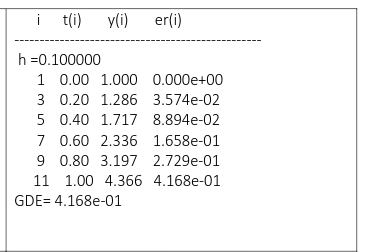

Ansatz 4:

Wir ermittelt **z** mit Hilfe des Newton verfahrens.

Das Newton muss so abgeändert werden, dass es F_euler aufruft.

*siehe newton2.m*

z0 = 0.1;
nmax = 10000;
tol = 10^(-100);
ti = 0;
yi = 1;
y_i(1) = yi;
[z,~,~] = newton2(f,df,ti,h,y_i(1),z0,tol,nmax)

nmax =        10000


z =    0.120000000000000


y_i(2) = y_i(1) + z;
ti = ti + h;
[z,~,~] = newton2(f,df,ti,h,y_i(2),z0,tol,nmax)

nmax =        10000


z =    0.148162073419617


y_i(3) = y_i(2) + z;
ti = ti + h;
[z,~,~] = newton2(f,df,ti,h,y_i(2),z0,tol,nmax)

nmax =        10000


z =    0.169328083908134


Vermutung:

Dies ist der richtige Ansatz

*Bemerkung:*

Jedoch ist das Ergebnis eher ungenau

Der Fehler entspricht:

e = abs(z - 0.1274)

e =    0.041928083908134


4. Zeitaufgelöste Simulation - MHD Ammar Aljouharji & Leonard Berresheim